warning('off','all')
clear
%%%% required parameters
envSize_X = 6;
envSize_Y = 6;
robotsPositions = [1 1.1; 2 1 ;2.5 1; 2 2; 3 1;1 3;1.5 4;2 3];
robotsPositions = rand(8,2)*envSize_Y        

robotsPositions =     2.2345    1.6147
    1.1887    2.5370
    2.9381    3.2872
    2.0370    5.6564
    5.7098    2.5065
    5.5220    5.8983
    0.3161    1.8087
    4.4271    4.2066


res = 0.1;
res = 1/res;
display = 1;
iterations = 50;
k = 1;
alpha = 1;
health = [1 1 1 0.1 1 1 1 1 ];
wts = [1 1 1 1 1 1 1 1  ];
loctaionalCostCell = cell(1,1);
filePath = append('/home/aimanmunir/Desktop/CoverageControlResults/AdaptiveTrust/envSize',num2str(envSize_Y),'/')

filePath = '/home/aimanmunir/Desktop/CoverageControlResults/AdaptiveTrust/envSize6/'

color = ["red","green","black","blue","yellow","cyan","magenta","#D95319"];

% Initial Voronoi 
% find its centroid
%%%%%%%%% For iterations
% show voronoi 
% getBoundary, Neighbors , Centroid, Mass
% Update weights
%%%%%%%%%%%%%%%%%%%%%% Conference Paper Eq 10 %%%%%%%%%%%%%%%%%%%%%
positionArray = cell(iterations+1,1);
robotsPositions = [1 1.1; 2 1 ;2.5 1; 2 2; 3 1;1 3;1.5 4;2 3];
r = transpose(robotsPositions);
lastPositions = robotsPositions;
positionArray{1} = [positionArray{1};robotsPositions];
[X,locations,locationIdxs,cellBoundaries,area] = partitionFinder(filePath,lastPositions,envSize_X, envSize_Y, wts,res,0, 'Initial voronoi partition',positionArray);

iter = 'Initial voronoi partition'

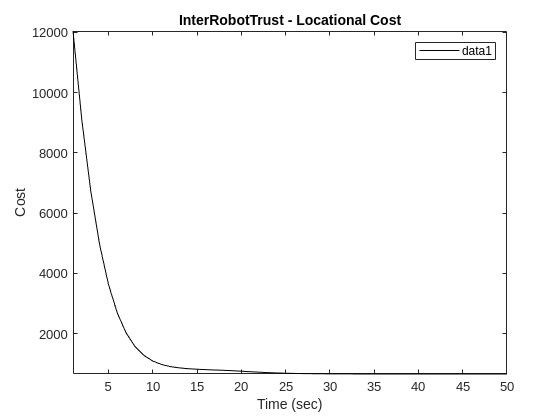

iter = '1'

iter = '2'

iter = '3'

iter = '4'

iter = '5'

iter = '6'

iter = '7'

iter = '8'

iter = '9'

iter = '10'

iter = '11'

iter = '12'

iter = '13'

iter = '14'

iter = '15'

iter = '16'

iter = '17'

iter = '18'

iter = '19'

iter = '20'

iter = '21'

iter = '22'

iter = '23'

iter = '24'

iter = '25'

iter = '26'

iter = '27'

iter = '28'

iter = '29'

iter = '30'

iter = '31'

iter = '32'

iter = '33'

iter = '34'

iter = '35'

iter = '36'

iter = '37'

iter = '38'

iter = '39'

iter = '40'

iter = '41'

iter = '42'

iter = '43'

iter = '44'

iter = '45'

iter = '46'

iter = '47'

iter = '48'

iter = '49'

iter = '50'

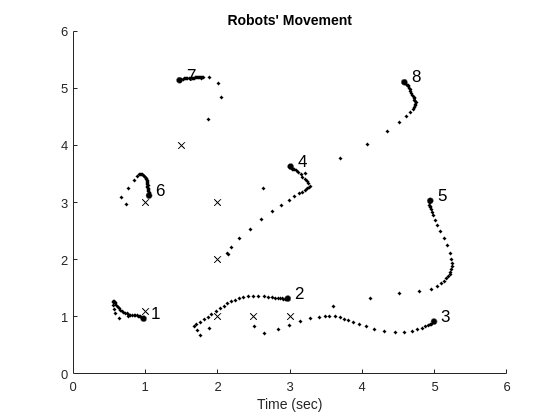

[C_x, C_y, locationalCost] = getCentroidForManualVoronoi_withCost(locations,1,robotsPositions,wts);
Mass = area;
density = getDensityValues_ManualVoronoi(X,0);
updatedWeights = transpose(wts);
iter = cell(1,1);
diffValues = cell( size(robotsPositions,1),1);
weightValues = cell( size(robotsPositions,1),1);
distValues = cell( size(robotsPositions,1),1);
for i= 1:iterations
    % Updated robots positions CX Cy
    robotsPositions_center = [C_x,C_y];
    robotsPositions_diff = ( robotsPositions_center-lastPositions);
    loctaionalCostCell{1} =[loctaionalCostCell{1},locationalCost];
    for r = 1:size(lastPositions,1)
        distanceCV= ( lastPositions(r,1)-C_x(r) )^2 + (lastPositions(r,2)-C_y(r))^2 ;
        dist = 1+ sqrt(distanceCV) ;
        u_ix = (robotsPositions_diff(r,1)/dist);
        u_iy = (robotsPositions_diff(r,2)/dist);
        KVALUES(r) = 1/dist;
        if(~isnan(u_ix))
            lastPositions(r,1) = lastPositions(r,1)+u_ix;
        else
            lastPositions(r,1) = lastPositions(r,1);
        end
        if(~isnan(u_iy))
            lastPositions(r,2) = lastPositions(r,2)+u_iy;
        else
            lastPositions(r,2) = lastPositions(r,2);
        end

    end
    positionArray{i+1} = [positionArray{i+1};lastPositions(:,1),lastPositions(:,2)];
    if(i~=iterations)
        [X,locations,locationIdxs,cellBoundaries,area] = partitionFinder(filePath,lastPositions,envSize_X, envSize_Y, updatedWeights ,res,0,num2str(i),positionArray);
    else
        [X,locations,locationIdxs,cellBoundaries,area] = partitionFinder(filePath,lastPositions,envSize_X, envSize_Y, updatedWeights ,res,1,num2str(i),positionArray);
    end

    [neighborsInfo,neighborsSharedBoundary,neighborsCount] = getNeighborsInformation_manualVoro(cellBoundaries);
    neighborsSharedBoundary;
    [C_x, C_y,locationalCost ] = getCentroidForManualVoronoi_withCost(locations,1, lastPositions,updatedWeights);
    lastWeights = updatedWeights;
    Mass = area;
    updatedWeights = UpdateWeights_eq10(cellBoundaries,density,neighborsCount,neighborsSharedBoundary,health,lastWeights,robotsPositions(:,1),robotsPositions(:,2),Mass,KVALUES , alpha);
    updatedWeights = lastWeights + updatedWeights;
    diff = updatedWeights - transpose(health);
    iter{1} = [iter{1},i];
    for r = 1:size(robotsPositions,1)
        diffValues{r} = [diffValues{r},[diff(r,:)]];
        weightValues{r} = [weightValues{r},[updatedWeights(r,:)]];
    end
end


updatedWeights

updatedWeights =     1.0419
    1.0419
    1.0419
    0.1419
    1.0419
    1.0419
    1.0419
    1.0419


area

area =     3.9650
    4.8550
    3.8850
    2.5450
    4.5800
    4.5200
    5.2150
    5.2300


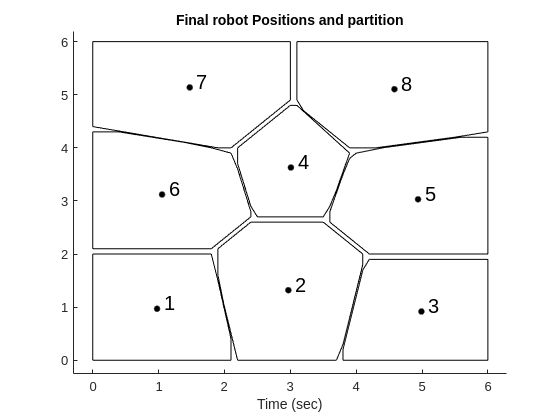

hold off;


figure;
for values = 1:size(robotsPositions,1)
    plot(iter{1},diffValues{values},Color="black");
    hold on;
end
title(" InterRobotTrust -  w_i - h_i")
        robotsPositions

robotsPositions =     1.0000    1.1000
    2.0000    1.0000
    2.5000    1.0000
    2.0000    2.0000
    3.0000    1.0000
    1.0000    3.0000
    1.5000    4.0000
    2.0000    3.0000


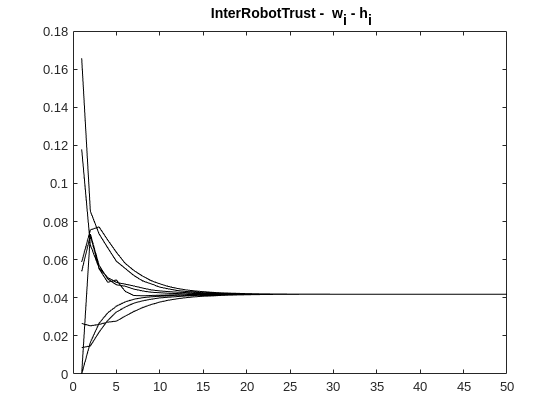

saveas(gcf, fullfile(filePath, "weightHealthDiff"), 'jpg');
hold off;

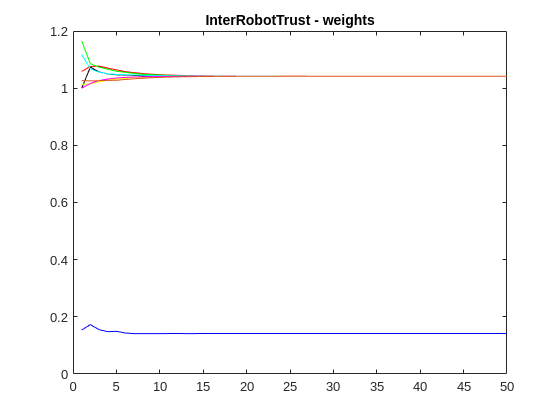


figure;
for values = 1:size(robotsPositions,1)
    plot(iter{1},weightValues{values},Color=color(values));
    hold on;
end
title("InterRobotTrust - weights")
saveas(gcf, fullfile(filePath,"Weights" ), 'jpg')

hold off;

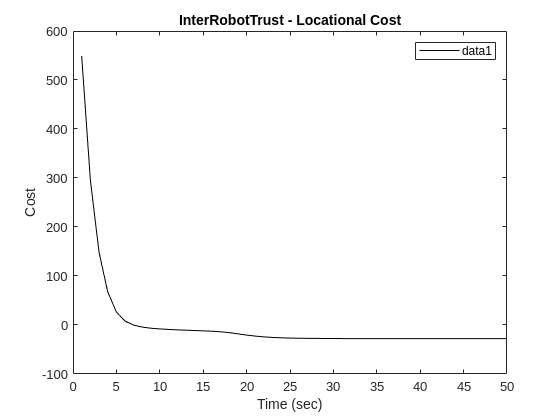


figure;
plot(iter{1},loctaionalCostCell{1},Color="black");
legend();
ylabel("Cost")
xlabel("Time (sec)")
title("InterRobotTrust - Locational Cost")
saveas(gcf, fullfile(filePath,"LocationalCost" ), 'jpg')
hold off;